# Example 3: Design of Experiments using TPMS

This example outlines the process for generating a full factorial design of experiments, by first defining the structure and levels.

## 3.1 Setting up

First, cleanup and set up the paths for data, results and filenames. Also decide what data needs to be calculated and what results we want to save. (Such as saving .stl/.inp/.png/.fig files)

clear variables
warning('off','all');

studyName = "ExampleStudy"; 
dataPath = 'data\';
plotFigures = 1;
saveFigures = 0;
saveSTL = 0;
calculatemechanical = 1;
calculatesurfaceMesh = 1;
curvaturemethod = 'none';

if saveFigures||saveSTL
    resultPath = "result\"+studyName+"\";
    if ~isfolder("result\"+studyName)
        mkdir("result\",studyName);
    end
    addpath(resultPath);
end


## 3.2 Define design parameters and levels

Here the variables which parametrically describe the TPMS-like structure are defined.

The **equation** of the tpms, **type** of structure, nodes per unit cell edge (**res**), and isovalues (**v**) define the fundamental structure form and discretisation. 

Alternatively the user my specify a target volume fraction (**vf**) in palce of the primary isovalue (**v1**).

DOE.res = [30]; % Resolution (nodes per cell)
DOE.v1 = [0.2,0.3]; % Primary isovalue/(target volume fraction)
DOE.v2 = [0]; % Secondary isovalue
DOE.equation = ["Gyroid", "Diamond"];% "Gyroid","Diamond","Primative", "Neovius", "IWP", "FRD"
DOE.type = ["surface","network"];% "network","double","surface"

A set of parametric affine transformations are defined using Cell Size (L) in mm, Offsets or phase shift (Bx,By,Bz) in mm, and euler rotations (Rx,Ry,Rz) in degrees.

DOE.L = 10; % Cell size (mm)
DOE.nx = [1]; %DOE.ny = 1; DOE.nz = 1; % Define number of cells
DOE.Bx = [0]; DOE.By = [0]; DOE.Bz = [0]; % Offsets: x,y,z
DOE.Rx = [0]; DOE.Ry = [0]; DOE.Rz = [0]; % Rotations: pitch,roll,yaw (deg)

## 3.3 Generate the DOE

Next we need to automatically set up the full-factorial design of experiments, including sample names.

Note that any values not set will default to a generally "safe" value when generating the structures.

names = string(fieldnames(DOE));
levels = zeros(length(names),1);
for i = 1:length(names)
    levels(i) = length(DOE.(names(i)));
end

doeFF = fullfact(levels);
doeArray = struct();

for i = 1:size(doeFF,1)
    for j = 1:size(names,1)
        doeArray(i,1).(names(j)) = DOE.(names(j))(doeFF(i,j));
    end
    % Create a name for the sample - you may wish to change this to show
    % more data
    doeArray(i,1).name = studyName+" "+num2str(i,'%4.0f');
end

## 3.4 Run the analysis

Set up the for loop to run each design. You may want to specify the level of analysis - (remembering mechanical, curvature, surfaceMesh will all add computational cost and time to every model).

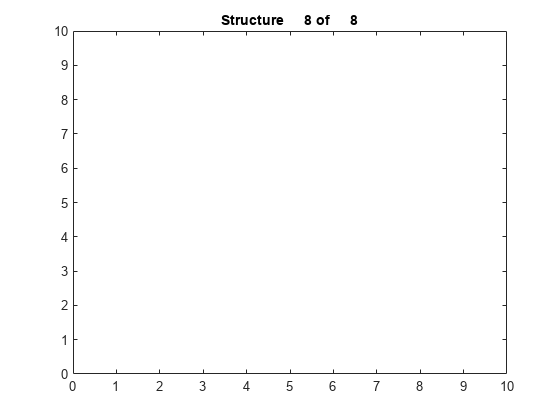

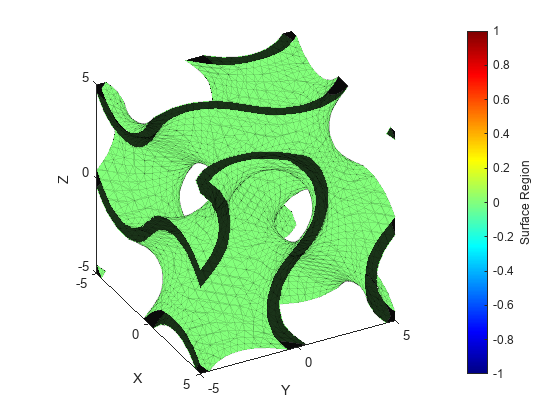

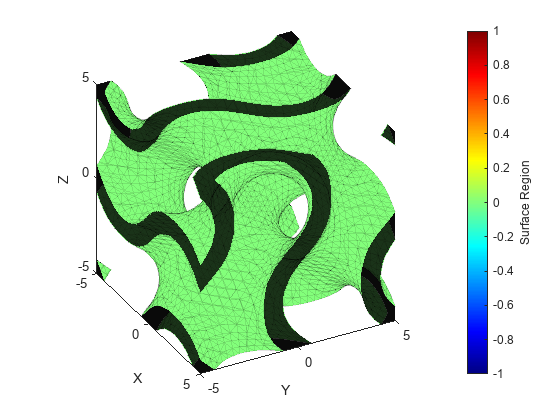

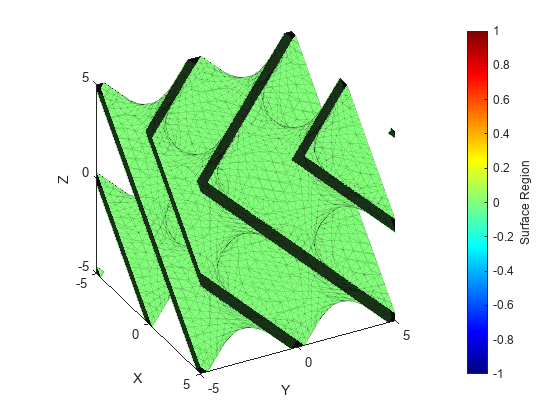

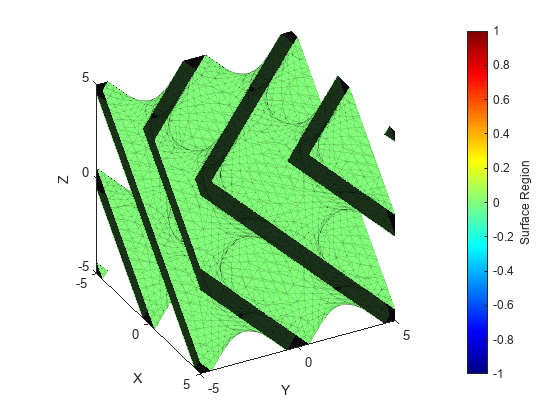

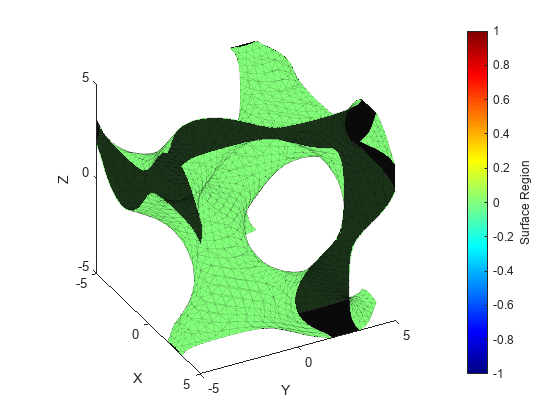

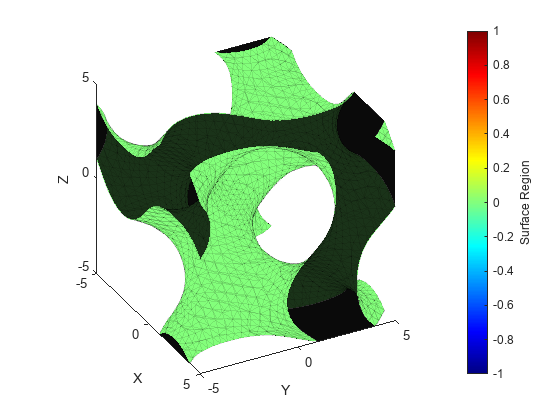

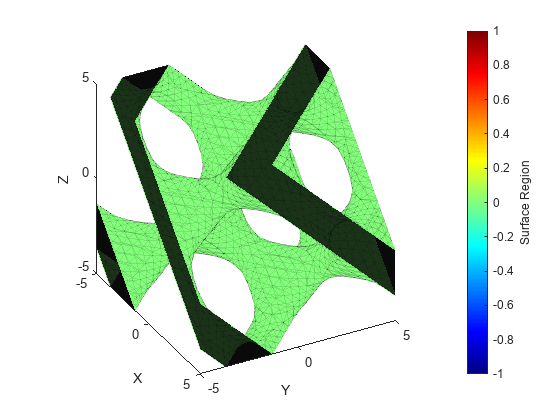

f = figure; ax = gca; % Figure and axis handles

for i = 1:size(doeArray,1)
    d = doeArray(i);
    TFORM = simtform3d(d.L,[d.Rx d.Ry d.Rz],[d.Bx d.By d.Bz]); 
    VOLUME = bulkSize('box',d.L.*[d.nx d.nx d.nx]); % Set to one unit cell in each direction 
    RES = [d.res,d.res,d.res].*[d.nx d.nx d.nx]; % Maintain consistant nodes per unit cell
    TPMS = UnitCell(d.type,d.equation,d.v1,d.v2,RES,TFORM,VOLUME);    %UnitCell = UnitCell(type,equation,v1,v2,res,tform,B)
    % Run full analysis - select (fields,mechanical,surfaceMesh,curvature)
    TPMS = TPMS.compute(curvaturemethod,calculatemechanical,calculatesurfaceMesh);
    % Export the metrics results and display the computational time
    DOEout(i,:) = [table(d.name) struct2table(TPMS.export,'AsArray',true)];
    
    % Preview the structure
    if plotFigures
        cla(ax)
        TPMS.plot("SurfaceMesh","none",[],ax);
        axis(ax,[0 d.L.*d.nx 0 d.L.*d.nx 0 d.L.*d.nx]);
        ax.Box = 'on';
        ax.BoxStyle = 'full';
    end
    Message = sprintf('Structure %5.0f of %5.0f',i,size(doeArray,1));
    title(ax,Message);  
    
    % Save figures as .png files in the results folder
    if saveFigures
        fid = strcat(resultPath,d.name,".png");
        saveas(f,fid,'png');
    end
    
    % Save mesh as .stl files in the results folder
    if saveSTL
        fid = strcat(resultPath,d.name,".stl");
        TPMS.FV.exportSTL(fid);
    end
    
    pause(0.01);
end

## 3.5 Post processing & Analysis

Set up the properties to plot (X vs Y scatterplots, with surface type grouping)

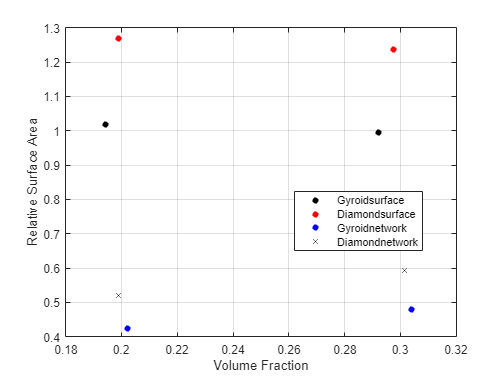

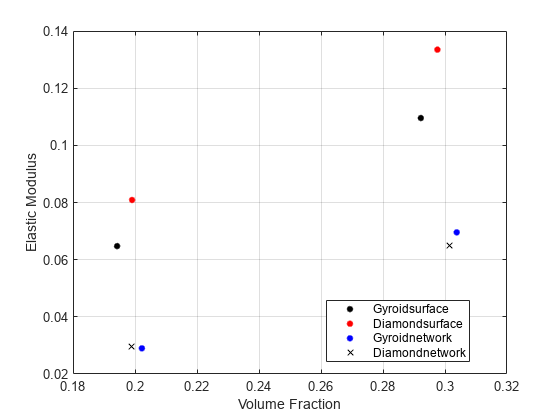

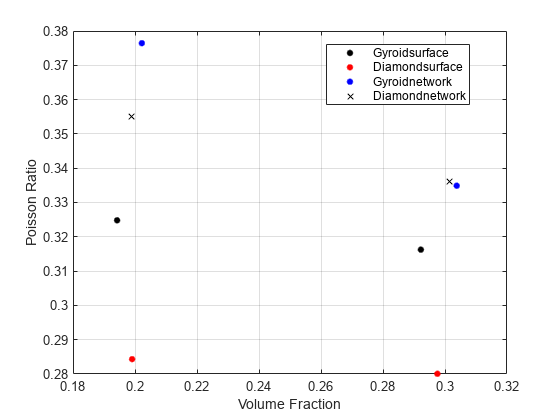

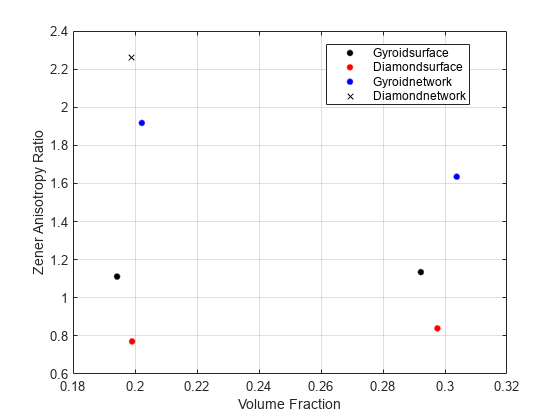

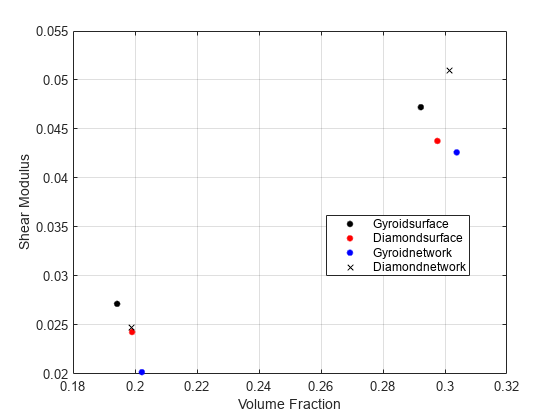

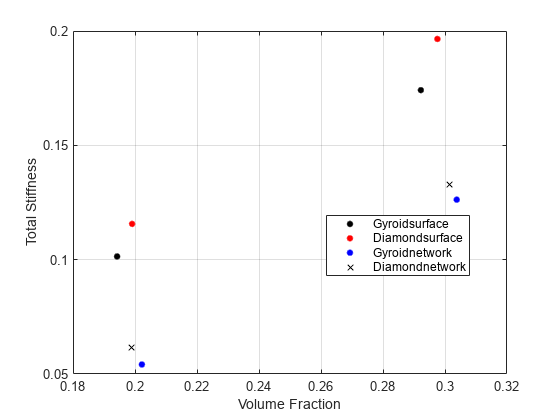

Yvars = ["relativeArea", "elastic", "poisson", "zenerRatio", "shear", "totalStiffness"];
plotlabels = ["Relative Surface Area", "Elastic Modulus", "Poisson Ratio", "Zener Anisotropy Ratio", "Shear Modulus", "Total Stiffness"];
Xvar = "relativeVolume";
grouping = strcat(DOEout.equation, DOEout.type);
% Set the datapoint colors and symbols
colors = [0 0 0; 1 0 0; 0 0 1;0 0 0; 1 0 0; 0 0 1];
sym = '...xxx';

%Make the plots
for i=1:length(Yvars)
    f = figure;
    ax = gca;
    L = gscatter(ax,DOEout.(Xvar),DOEout.(Yvars(i)),grouping,colors,sym);
    hold on;
    xlabel('Volume Fraction');
    ylabel(plotlabels(i));
    grid on;
end

## 3.6 DOE Analysis (Main effects/interactions)

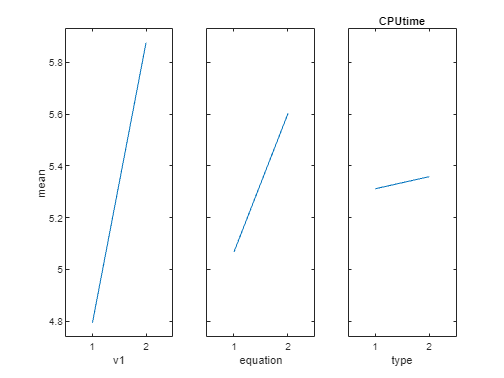

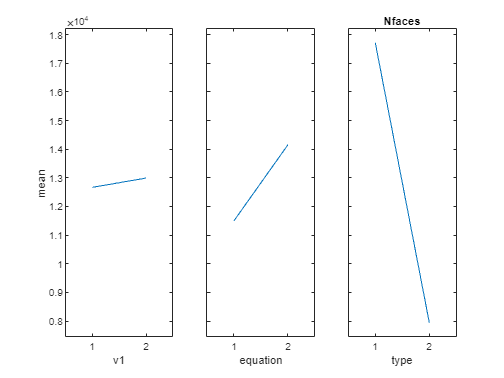

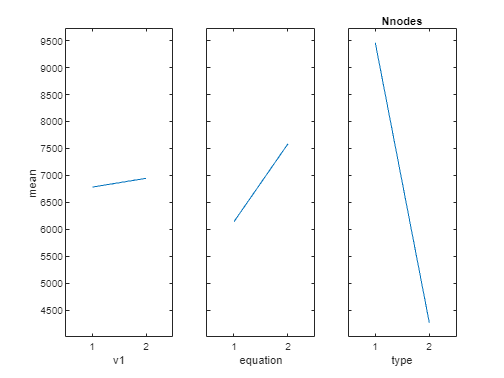

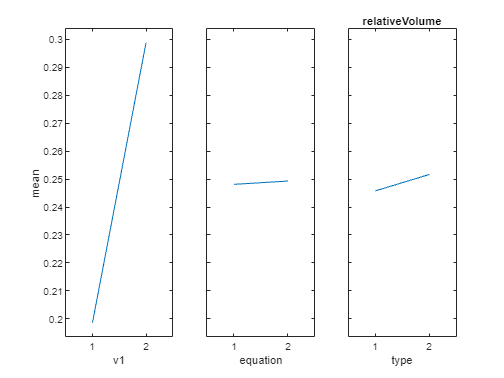

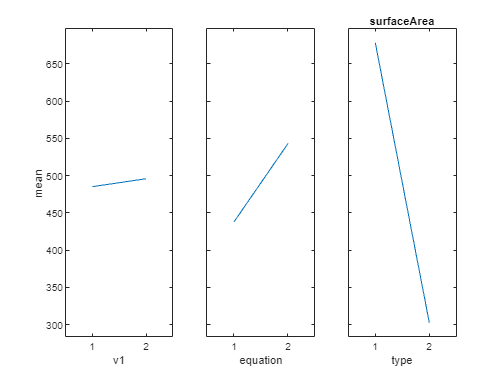

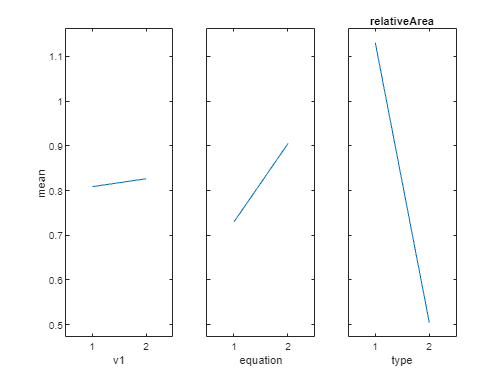

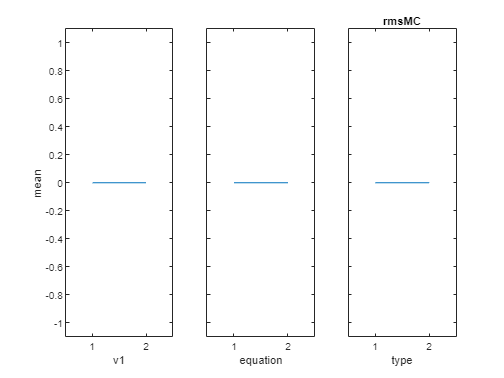

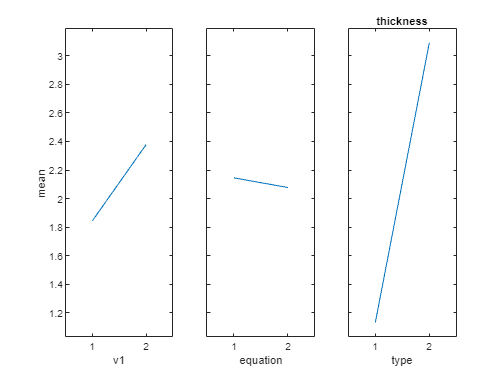

% List of variables to plot main effects of
Yvars = ["CPUtime","Nfaces","Nnodes","relativeVolume","surfaceArea","relativeArea","rmsMC","thickness","poreDiameter","areaVar","areaMean","areaStd", "elastic", "poisson","shear", "totalStiffness","zenerRatio"];

for i = 1:length(Yvars)
    figure('Name',Yvars(i));
    maineffectsplot(DOEout.(Yvars(i)),doeFF(:,levels>1),'varnames',names(levels>1,:));
    a = gca;
    title(a,Yvars(i));
end

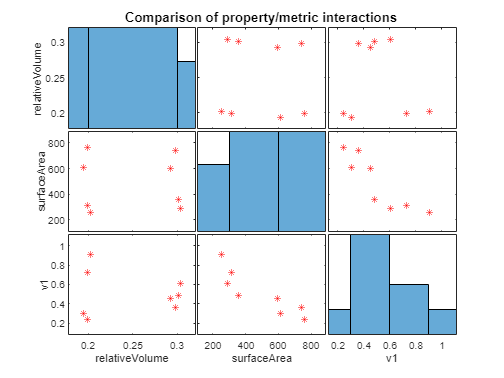

% Conduct an investigation of relationships between ANY input and/or output values using a plot-matrix
Yvars = ["relativeVolume" "surfaceArea" "v1"];
[S,AX,BigAx,H,HAx] = plotmatrix(table2array(DOEout(:,Yvars)),'*r');
title(BigAx,'Comparison of property/metric interactions');

% Add axis labels
for i=1:length(Yvars)
    ylabel(AX(i,1),Yvars(i));
    xlabel(AX(length(Yvars),i),Yvars(i));
end